# Training data 

More on [https://github.com/slevin48/gta](https://github.com/slevin48/gta) 

## Get Data from dumped images

training_data_0 = imread("screenshots\training_data-2021-02-12-2\screenshots1\training_data_0.jpg")

training_data_0 = 270×480×3 uint8 array
training_data_0(:,:,1) =

   154   155   151   150   150   153   155   149   153   152   148   149   148   148   148   145   137   134   135   135   133   136   140   138   134   137   134   129   127   123   108    99   101   103   103    96   101   108   103   100   103   104   102   100   102   104   102    96    95    95    89    86    89    80    81    79    76    66    66    54    56   101   145   162   157   151   159   140    59    82    61    45   162   102   100    61    89    48    40    49    47    18    56    46    50    72   100    56    68    96    55    63    92    81    49    55    62    57    48    37    55    36    15    95    97    72    39    41    40    38    49    49    66    61    66    61    53    67    52    63    71    88    52    58    61    47    37   109   103    67    98    78    60    47   110   119   158   189   184   181   184   182   179   180   184   181    34    22    41   125   111   109    91   107    80   2

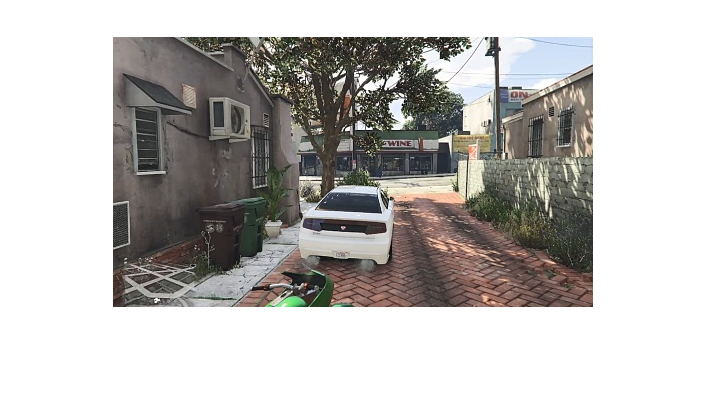

imshow(training_data_0)

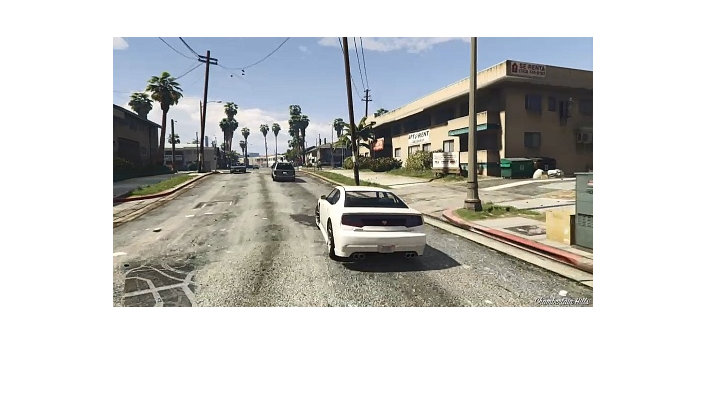

i = 400;
training_data = imread("screenshots\training_data-2021-02-12-2\screenshots1\training_data_"+string(i)+".jpg");
imshow(training_data)

## Get controller inputs

k = 1;
timeline = readtable("timeline\training_data-2021-02-12-2\timeline"+string(k)+".csv")

timeline = 500×2 table
    Var1             time          
    ____    _______________________

      0     2021-02-12 19:40:46.253
      1     2021-02-12 19:40:46.279
      2     2021-02-12 19:40:46.313
      3     2021-02-12 19:40:46.344
      4     2021-02-12 19:40:46.361
      5     2021-02-12 19:40:46.379
      6     2021-02-12 19:40:46.411
      7     2021-02-12 19:40:46.428
      8     2021-02-12 19:40:46.446
      9     2021-02-12 19:40:46.481
     10     2021-02-12 19:40:46.513
     11     2021-02-12 19:40:46.546
     12     2021-02-12 19:40:46.578
     13     2021-02-12 19:40:46.612
     14     2021-02-12 19:40:46.646
     15     2021-02-12 19:40:46.681


## Get keyboard inputs

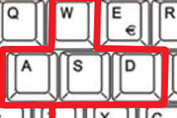

**/!\**** Q instead of A for French keyboard here!!!**

T = readtable("keyboard/training_data-1.csv");
T = renamevars(T,"Var1","ID")

T = 500×10 table
    ID    W    S    Q    D    WQ    WD    SQ    SD    NOKEY
    __    _    _    _    _    __    __    __    __    _____

     0    0    0    0    0    0     0     0     0       1  
     1    0    0    0    0    0     0     0     0       1  
     2    0    0    0    0    0     0     0     0       1  
     3    0    0    0    0    0     0     0     0       1  
     4    0    0    0    0    0     0     0     0       1  
     5    0    0    0    0    0     0     0     0       1  
     6    0    0    0    0    0     0     0     0       1  
     7    0    0    0    0    0     0     0     0       1  
     8    0    0    0    0    0     0     

T(T.D == 1,:) % Turning right

ans = 18×10 table
    ID     W    S    Q    D    WQ    WD    SQ    SD    NOKEY
    ___    _    _    _    _    __    __    __    __    _____

    212    0    0    0    1    0     0     0     0       0  
    213    0    0    0    1    0     0     0     0       0  
    214    0    0    0    1    0     0     0     0       0  
    215    0    0    0    1    0     0     0     0       0  
    216    0    0    0    1    0     0     0     0       0  
    359    0    0    0    1    0     0     0     0       0  
    360    0    0    0    1    0     0     0     0       0  
    361    0    0    0    1    0     0     0     0       0  
    362    0    0    0    1    

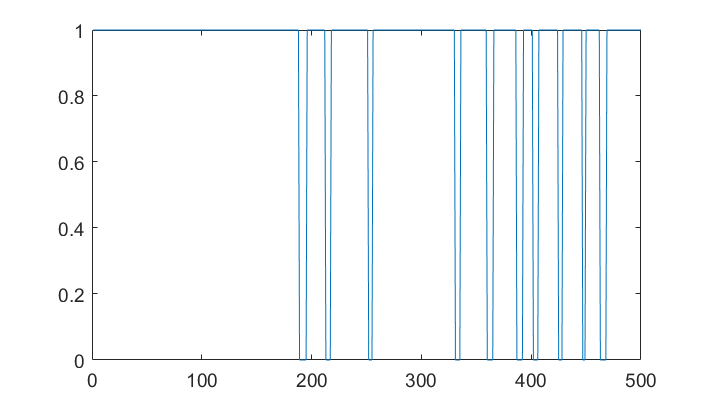

plot(T.NOKEY)

## Get data from Numpy directly

pyenv

training_data = dir("training_data\training_data-2021-02-12-2");
training_data = training_data(3:end,:)

training_data = 23×1 struct array with fields:
    name
    folder
    date
    bytes
    isdir
    datenum


length(training_data)

ans = 23

nb_train = 3;
% npdata = py.numpy.load("training_data\training_data-"+string(nb_train)+".npy")
npdata = py.training_data.load_data("training_data\training_data-"+string(nb_train)+".npy")

npdata =   Python list with no properties.

    [array([[[216, 200, 190],
            [216, 200, 190],
            [216, 200, 190],
            ...,
            [215, 202, 190],
            [215, 202, 190],
            [215, 202, 190]],
    
           [[216, 200, 190],
            [216, 200, 190],
            [216, 200, 190],
            ...,
            [215, 202, 190],
            [214, 202, 189],
            [214, 201, 188]],
    
           [[218, 201, 192],
            [217, 200, 190],
            [217, 200, 191],
            ...,
            [213, 200, 188],
            [214, 201, 188],
            [214, 201, 188]],
    
           ...,
    
           [[ 83, 110, 120],
            [ 84, 112, 121],
            [ 83, 111, 120],
            ...,
            [ 52,  81,  92],
            [ 45,  70,  82],
            [ 47,  71,  84]],
    
           [[ 79, 106, 116],
            [ 87, 114, 123],
            [ 82, 110, 1

mdata = cell(npdata)

mdata = 1×500 cell array
  Columns 1 through 384

    {1×1 py.numpy.ndarray}    {1×1 py.numpy.ndarray}    {1×1 py.numpy.ndarray}    {1×1 py.numpy.ndarray}    {1×1 py.numpy.ndarray}    {1×1 py.numpy.ndarray}    {1×1 py.numpy.ndarray}    {1×1 py.numpy.ndarray}    {1×1 py.numpy.ndarray}    {1×1 py.numpy.ndarray}    {1×1 py.numpy.ndarray}    {1×1 py.numpy.ndarray}    {1×1 py.numpy.ndarray}    {1×1 py.numpy.ndarray}    {1×1 py.numpy.ndarray}    {1×1 py.numpy.ndarray}    {1×1 py.numpy.ndarray}    {1×1 py.numpy.ndarray}    {1×1 py.numpy.ndarray}    {1×1 py.numpy.ndarray}    {1×1 py.numpy.ndarray}    {1×1 py.numpy.ndarray}    {1×1 py.numpy.ndarray}    {1×1 py.numpy.ndarray}    {1×1 py.numpy.ndarray}    {1×1 py.numpy.ndarray}    {1×1 py.numpy.ndarray}    {1×1 py.numpy.ndarray}    {1×1 py.numpy.ndarray}    {1×1 py.numpy.ndarray}    {1×1 py.numpy.ndarray}    {1×1 py.numpy.ndarray}    {1×1 py.numpy.ndarray}    {1×1 py.numpy.ndarray}    {1×1 py.numpy.ndarray}    {1×1 py.numpy.ndarray}    {1×1 py.nu

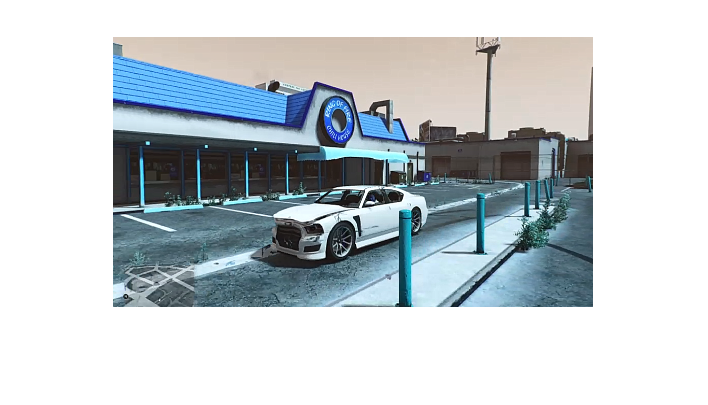

imshow(uint8(mdata{1}))

### Specify data

dataFolder = "screenshots\training_data-2021-02-12-2\screenshots1";
% renameImages(dataFolder); % only need to be run once
imds = imageDatastore(dataFolder);

### Aside : what does a pre-trained ACF detector give us ?

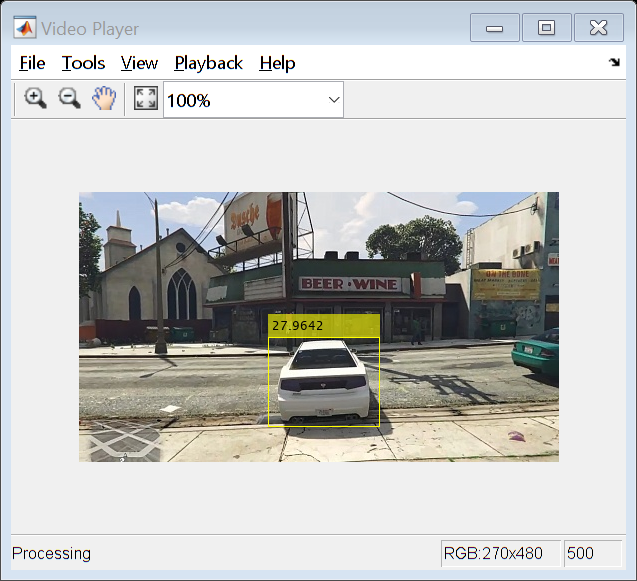

detector = vehicleDetectorACF('front-rear-view');
vp = vision.VideoPlayer ;

reset(imds);
reset(vp)
while hasdata( imds )
    I = read( imds );
    [bboxes,scores] = detect(detector,I);
    if ~isempty( bboxes )
        I = insertObjectAnnotation(I,'rectangle',bboxes,scores);
    end
    step( vp, I )
    drawnow
end

### Deep Learning

Read in response data and reformat 

T = readtable("training_data-3.csv");
numPoints = size(T, 1);
right = T.D ;
left = T.Q ;
straight = double(~( logical( right) | logical(left) ));
labels = straight + 2*left + 3*right;
imds.Labels = categorical(labels);

Resize input data to match network architecture

outputSize = [227 227];
auimds = augmentedImageDatastore(outputSize, imds);

### Use Deep Network Designer to do transfer learning

In this case, using AlexNet for transfer learning does not work as the training is not converging. We need more data, and also to revisit how the problem is formulated. 

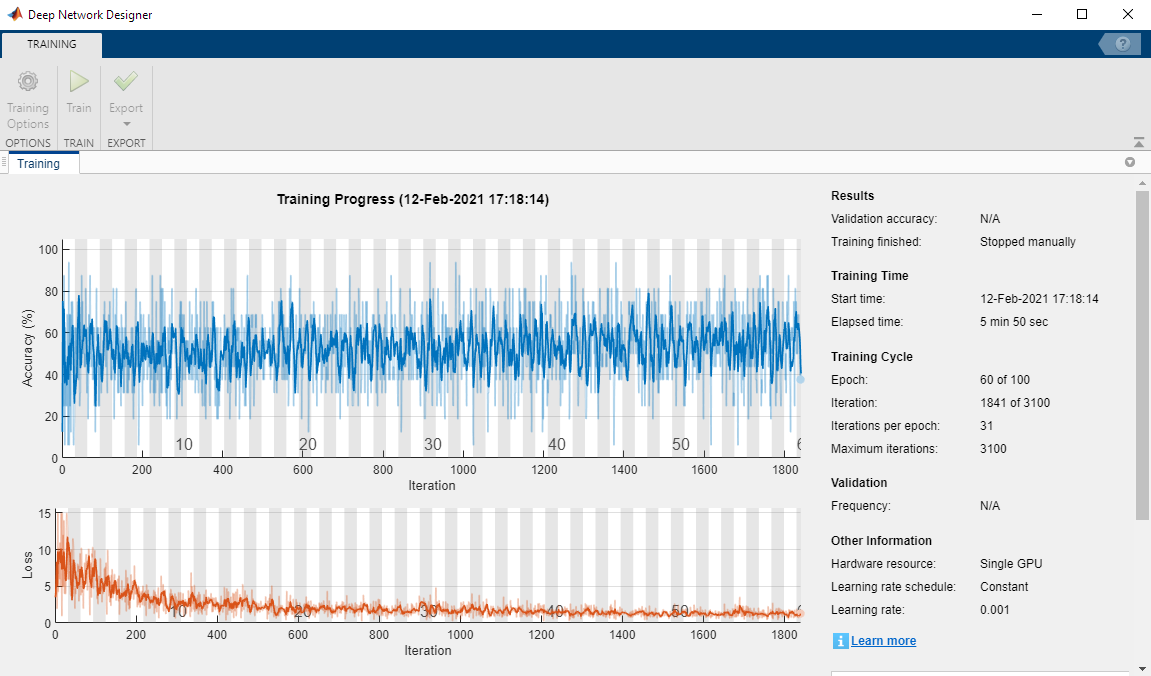

### Helper function

function renameImages( dataFolder )

D = dir(dataFolder);
nameRoot = "training_data_";
for i = 1:numel(D)
    if D(i).isdir == 0
        
        I = imread(fullfile(dataFolder, D(i).name));
        [~,filename,ext] = fileparts(D(i).name);
        nameLength = length( filename );
        if nameLength == 17
            continue;
        else
            if nameLength == 15
                imNumber = ["00" + filename(15)] ;
            elseif nameLength == 16
                imNumber = ["0" + filename(15:16)];                
            end
            newFilename = [nameRoot + imNumber + ext];
            imwrite(I, fullfile(dataFolder, newFilename));
            delete(fullfile(dataFolder, D(i).name));
        end
    end
end

end